# Visual example of kurtosis in distribution

Kurtosis is a statistical measure that describes the shape of a distribution's tails in relation to its peak, reflecting the distribution's extremeness or outliers. It is a part of the fourth moment of a distribution and provides insight into the concentration of data points in the tails and the sharpness of the peak compared to a normal (Gaussian) distribution. Kurtosis is an important concept in statistics because it helps in understanding the likelihood of extreme values in a dataset.

**Formula**


$$\mathrm{Kurtosis}=\frac{E\left\lbrack {\left(X-\mu \right)}^4 \right\rbrack }{\sigma^4 }$$


where *E* is the expected value operator, *X* is the random variable, *μ* is the mean of the distribution, and *σ* is the standard deviation. The result describes how outlier-prone a distribution is. For practical purposes, often the "excess kurtosis" is reported, which is the kurtosis of the distribution minus 3 (the kurtosis of a normal distribution). This makes the normal distribution have an excess kurtosis of 0, simplifying comparisons.

Understanding kurtosis is crucial in various fields, including finance, where it can indicate the risk of extreme price movements, and in quality control and operational research, where it helps in identifying the presence of outliers or potential issues in data sets.

**Shape of a distribution (Likelihood of extreme values in a dataset)**

- Mesokurtic: This is the classification for a distribution that has kurtosis similar to that of a normal distribution, which is considered to have a kurtosis of 3 (using the excess kurtosis measurement, it is 0). A mesokurtic distribution has a moderate peak and tails, indicating a balanced distribution of data points around the mean.

- Leptokurtic: A distribution is described as leptokurtic when it has a kurtosis greater than that of a normal distribution (excess kurtosis > 0). These distributions are characterized by a sharper peak and fatter tails, indicating a higher probability of extreme values or outliers. This means that data are more clustered around the mean, with more frequent large deviations from the mean than would be expected in a normal distribution.

- Platykurtic: This term describes distributions with a kurtosis less than that of a normal distribution (excess kurtosis < 0). Platykurtic distributions have a flatter peak and thinner tails compared to a normal distribution, suggesting a lower probability of extreme values. The data points are more spread out from the mean, with fewer large deviations compared to a normal distribution.

**Number of samples**

N = 1e6;

***Mesokurtic distribution***** (normal distribution)**

mesokurtic = randn(N, 1); % Standard normal distribution

***Leptokurtic distribution***** (with higher kurtosis)**

% We can use a t-distribution with low degrees of freedom for leptokurtosis
df = 3; % Degrees of freedom for the t-distribution
leptokurtic = trnd(df, N, 1);


***Platykurtic distribution***** (with lower kurtosis)**

% Uniform distribution has lower kurtosis than normal distribution
a = -sqrt(3); b = sqrt(3); % Parameters for uniform distribution to have variance=1
platykurtic = a + (b-a).*rand(N, 1);

**Visualization of Distributions**

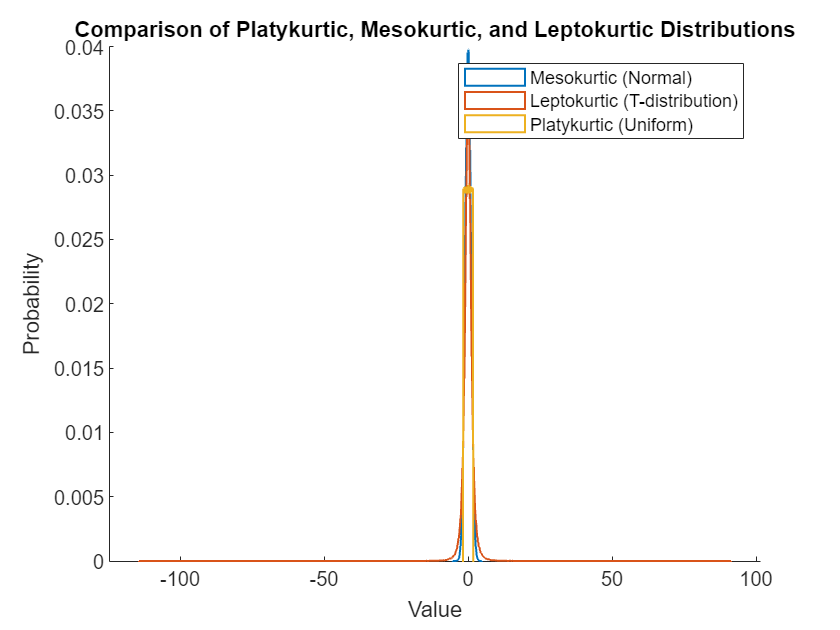

% Plotting
figure;
hold on;

% Histogram of mesokurtic distribution
histogram(mesokurtic, 'Normalization', 'probability', 'BinWidth', 0.1, 'DisplayStyle', 'stairs', 'LineWidth', 1);
% Histogram of leptokurtic distribution
histogram(leptokurtic, 'Normalization', 'probability', 'BinWidth', 0.1, 'DisplayStyle', 'stairs', 'LineWidth', 1);
% Histogram of platykurtic distribution
histogram(platykurtic, 'Normalization', 'probability', 'BinWidth', 0.1, 'DisplayStyle', 'stairs', 'LineWidth', 1);

title('Comparison of Platykurtic, Mesokurtic, and Leptokurtic Distributions');
xlabel('Value');
ylabel('Probability');
legend({'Mesokurtic (Normal)', 'Leptokurtic (T-distribution)', 'Platykurtic (Uniform)'});

hold off;